clc, clear, close all;


## Load data

base_sample_rate = 1000;
emg_sample_rate = 1000;

AddPaths()

Linux


filename_EMG = 'EMG_SECOND_PLAY_CHOPIN_C.txt';
[~, emg_muscle1, emg_muscle2] = ReadEMG(filename_EMG, emg_sample_rate, base_sample_rate);

filename_EMG = 'EMG_MVC_001.txt';
[~, mvc_muscle1, mvc_muscle2] = ReadEMG(filename_EMG, emg_sample_rate, base_sample_rate);

## Convert to mV

n = 12; VCC = 3; Gemg = 1000;
DigTomV = @(adc) (((adc./2.^n - 1/2) .* VCC) ./ Gemg) * 1000;

mV_muscle1 = DigTomV(emg_muscle1);
mV_muscle2 = DigTomV(emg_muscle2);
mV_mvc1 = DigTomV(mvc_muscle1);
mV_mvc2 = DigTomV(mvc_muscle2);

max(mV_muscle1)

ans =                     1.3125


max(mV_mvc1)

ans =               1.4501953125


## Filter data

### Settings

f_low = 10;     % Lower cutoff frequency
f_high = 250;   % Upper cutoff frequency
freq_range = [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)];
filter_order = 4;

x_start = 37800; x_stop = 40000;

### Filters

% Design the Butterworth bandpass filter
[b, a] = butter(filter_order, [f_low/(emg_sample_rate/2), f_high/(emg_sample_rate/2)], 'bandpass');

% https://nl.mathworks.com/matlabcentral/answers/1704910-bandpass-uses-filtfilt-not-filter
[y, d] = bandpass(mV_muscle1, freq_range, 'ImpulseResponse', 'iir', 'Steepness', 0.75);

### Plot filter

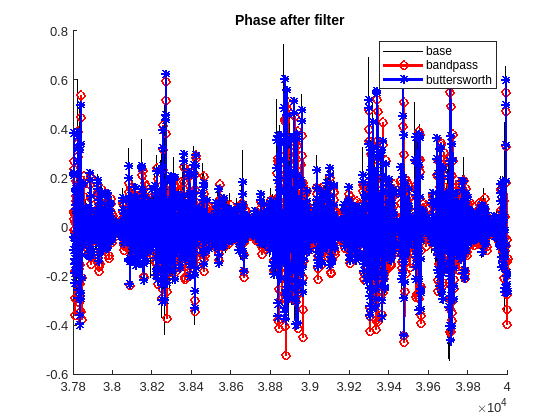

f_x_band = filter(d, mV_muscle1);
f_x_butt = filter(b, a, mV_muscle1);
figure; hold on
plot(mV_muscle1, 'k', 'LineWidth', 1);
plot(f_x_band, 'or-', 'LineWidth', 2);
plot(f_x_butt, '*b-', 'LineWidth', 2);
xlim([x_start, x_stop])
title("Phase after filter");
legend("base", "bandpass", "buttersworth");
hold off

### Plot filtfilt

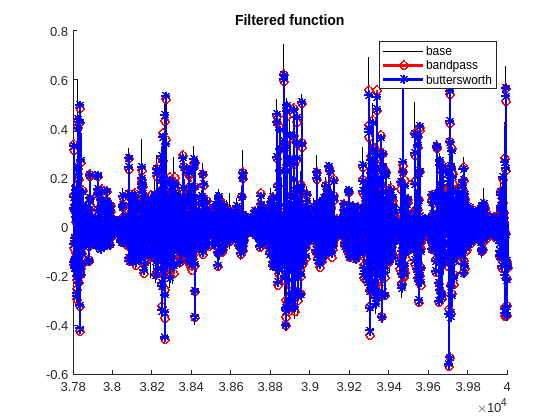

ff_x_band = filtfilt(d, mV_muscle1);
ff_x_butt = filtfilt(b, a, mV_muscle1);
figure; hold on
plot(mV_muscle1, 'k', 'LineWidth', 1);  
plot(ff_x_band, 'or-', 'LineWidth', 2);
plot(ff_x_butt, '*b-', 'LineWidth', 2);
xlim([x_start, x_stop])
title("Filtered function");
legend("base", "bandpass", "buttersworth");
hold off

filt_muscle1 = filtfilt(b, a, mV_muscle1);
filt_muscle2 = filtfilt(b, a, mV_muscle2);
filt_mvc1 = filtfilt(b, a, mV_mvc1);
filt_mvc2 = filtfilt(b, a, mV_mvc2);

## Normalize data

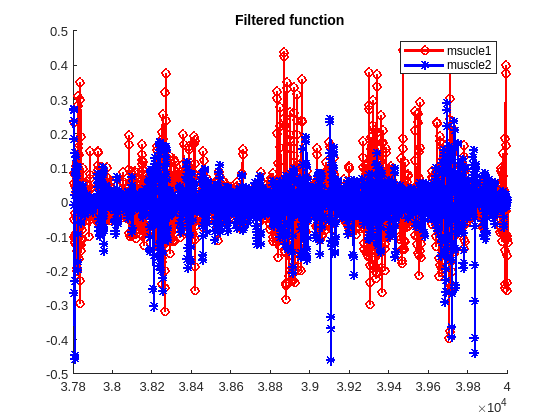

norm_muscle1 = filt_muscle1/max(filt_mvc1);
norm_muscle2 = filt_muscle2/max(filt_mvc2);

figure; hold on
plot(norm_muscle1, 'or-', 'LineWidth', 2);
plot(norm_muscle2, '*b-', 'LineWidth', 2);
xlim([x_start, x_stop])
title("Filtered function");
legend("msucle1", "muscle2");
hold off

## Correlate